clear; clc;
% cd ~/git/hardDiskControl/discreteTimeControl/
load ../data/sysDT.mat
load ../data/Gz.mat
load ../data/plantTF.mat
load ../data/sysCT.mat

riseTime = 0.052333; %seconds
Ts = riseTime/10;

Q = diag([0 0 2E3 1E8]);
R = [0];
[X,Klqr,L] = idare(sysDT.A,sysDT.B,Q,R);
sysLQR = ss(sysDT.A-sysDT.B*Klqr,sysDT.B,sysDT.C,sysDT.D,Ts);
sysLQR.B = sysLQR.B*dcgain(sysLQR)^-1;

now we will create the delayed system

Ad = [sysLQR.A sysLQR.B;
      zeros(1,4) 0];
Bd = [zeros(4,1); 1];
Cd = [sysLQR.C 0];
Dd = sysLQR.D;
sysLQRd = ss(Ad,Bd,Cd,Dd,Ts);

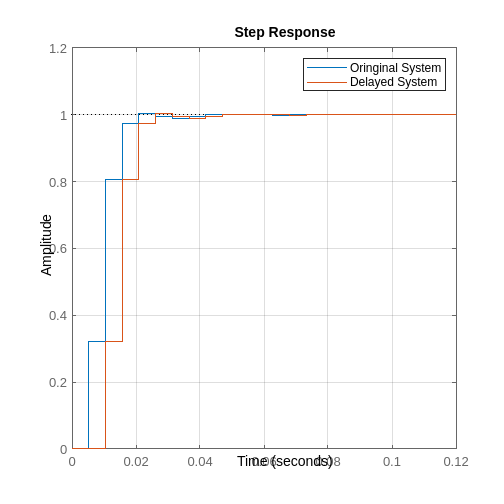

figure('Position', [0 0 1000 1000]);clf;hold on;
step(sysLQR)
step(sysLQRd); grid on;
legend("Oringinal System", "Delayed System")